# Getting simulated data from an AR model

## Introduction

In this tutorial you will learn how to simulate time series from a univariate random process defined by an AR model. 

The dataset employed in this tutorial is '*database/case_03_AR*', which includes a restricted AR model employed in Section 3.1 of** [1]**. In this tutorial, a number of arbitraty $k$ realisations of the process is performed. As a result, $k$ time series of length $N$ are obtained and stored in a `data` object.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

k = 5;      % number of realisations of the process
N = 1000;   % data length

M = 50;     % maximum lag for the autocovariance functions


%%% Plot parameters
font_size       = 16;
figure_position = [0 0 1000 400];
CC              = colororder;
alpha           = 0.9;
color_realisations = [0.5*[1 1 1] alpha];
color_true = [CC(1,:) alpha];

Load the dataset. It consists of a restricted AR model. Check the fields required by function `get_gamma_AR`. For details related to the fields of these objects, see functions `initialise_`AR.

load case_03_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Initialise a `data` object with the fields required by function `get_data_AR`.

data = initialise_data('N',N,'k',k);

Obtain the realisations.

data = get_data_AR(AR, data);

Plot the time series

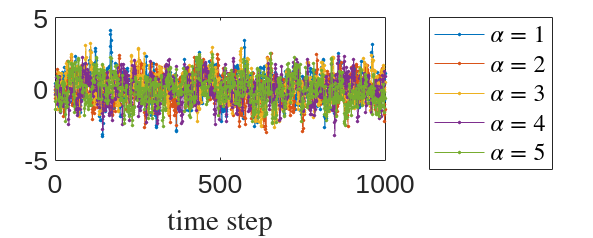

figure

y = data.y_values;
plot(y,'.-')
xlabel('time step','Interpreter','latex')
legend(strcat(['Realisation',' '],num2str((1:k)')),'location','eastoutside')
legend(strcat('$\alpha= ',strcat(num2str((1:k)'),'$')),...
       'Interpreter','latex','Location','eastoutside')

set(gca,'fontsize',font_size)

set(gcf,'Position',figure_position)

You can add a $\Delta t$ to field `delta_x` in data object using function `fun_append_data`. By doing so, field `data.x_values` is automatically filled (this operation is handled by `fun_check_data`, called at the end of `fun_append_data`).

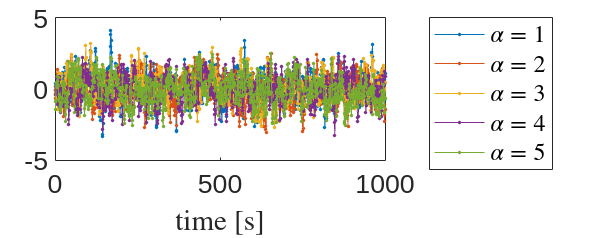

delta_t = 0.05;

data = fun_append_data(data,'delta_x',delta_t);

figure

x = data.x_values;
y = data.y_values;
plot(y,'.-')
xlabel('time [s]','Interpreter','latex')
legend(strcat(['Realisation',' '],num2str((1:k)')),'location','eastoutside')
legend(strcat('$\alpha= ',strcat(num2str((1:k)'),'$')),...
       'Interpreter','latex','Location','eastoutside')

set(gca,'fontsize',font_size)

set(gcf,'Position',figure_position)

In order to check that the generated time series reproduce the statistical features of the AR model, the true autocovariance function of the AR model and the estimated autocovariance functions from the data are to be compared. For more details on these operations, check tutorials *getting_gamma_from_AR* and *getting_gamma_from_data*.

Get the true autocovariance function of the AR model.

gamma_fun0 = initialise_gamma('M', M);
gamma_fun_AR = get_gamma_AR (AR, gamma_fun0);

Get the estimated autocovariance function of the data.

gamma_fun0 = initialise_gamma('method', 'biased_matlab', 'M', M);

for ii=1:k
    k_index = ii;
    gamma_fun_data = get_gamma_data(data, gamma_fun0, k_index);
    gamma_fun_data_cell{ii} = gamma_fun_data;
end


Plot the obtained autocovariance functions.

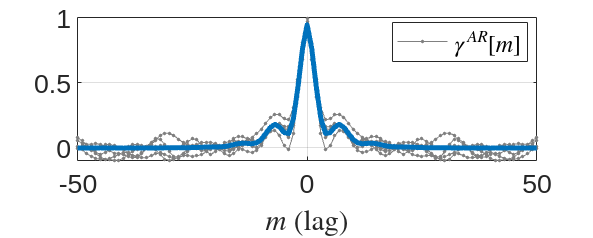

figure

for ii=1:k
    gamma_fun_data = gamma_fun_data_cell{ii};
    x = gamma_fun_data.xlag_values;
    y = gamma_fun_data.y_values;
    plot(x,y,'.-','color',color_realisations)
    hold on
end

x = gamma_fun_AR.xlag_values;
y = gamma_fun_AR.y_values;
plot(x,y,'-','LineWidth',3,'color',color_true)

grid on
legend({'$\gamma^{AR}[m]$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$m$ (lag)','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the *x*-axis is for lags, which are stored in field `gamma_fun.xlag_values`. The field `gamma_fun.x_values` is for cases in which the sampling time, $\Delta t$, is known, so that the autocovariance function can be represented as a function of time (or space).